%data = load('SineWave{1}{6}.Values.Da');
t = SineWave{1}{6}.Values.Time;    % Time

Undefined variable 'SineWave'.

omega = SineWave{1}{6}.Values.Data;
V = SineWave{1}{3}.Values.Data

% 
% function omega_est = motor_model(params, t, V)
%     % Extract parameters
%     Rm = params(1);
%     Lm = params(2);
%     Ke = params(3);
%     Km = params(3)*params(6);
%     Jm = params(4);
%     Bm = params(5);
%     eta = params(6);
% 
%     s = tf('s'); 
% 
%     I_tf = 1 / (Lm * s + Rm);
% 
%     Omega_tf = (eta * Km * I_tf) / (Jm * s + Bm + Ke * Km / Rm);
% 
%     omega_est = lsim(Omega_tf, V, t);
% end


% function cost = cost_function(params, t, V, omega_measured)
%     omega_est = motor_model(params, t, V);
%     cost = double(sum((omega_measured - omega_est).^2)); % Ensure double type
% end
% 
% function cost = cost_function_nmse(params, t, V, omega_measured)
%     omega_est = motor_model(params, t, V);
%     cost = double(sum((omega_measured - omega_est).^2) / sum(omega_measured.^2));
% end
% 
% function cost = cost_function_absolute(params, t, V, omega_measured)
%     omega_est = motor_model(params, t, V);
%     cost = double(sum(abs(omega_measured - omega_est))); % Ensure double type
% end
% 


% Initial parameter guesses: [Rm, Lm, Ke, Km, Jm, Bm, eta]
params_init = [4.5, 0.004, 0.05, 0.001, 0.0001, 0.5];
% motor_Eff = 0.5;
% motor_Ke = 0.05;
% motor_J = 0.001;
% motor_B = 0.0001;

lb = [1e-09, 1e-09, 1e-09, 1e-09, 1e-09, 1e-09];  % Minimum bound for all
ub = [Inf, Inf, Inf, Inf, Inf, 1];  % Efficiency (eta) max is 1

% Optimize using `fmincon` for different cost functions
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9); % Tight convergence settings

% estimated_params = fmincon(@(p) cost_function(p, t, V, omega), params_init, [], [], [], [], lb, ub);
estimated_params_nmse = fmincon(@(p) cost_function_nmse(p, t, V, omega), params_init, [], [], [], [], lb, ub);
% estimated_params_absolute = fmincon(@(p) cost_function_absolute(p, t, V, omega), params_init, [], [], [], [], lb, ub, [], options);

% Rm_hat = estimated_params(1);
% Lm_hat = estimated_params(2);
% Ke_hat = estimated_params(3);
% Km_hat = estimated_params(3)*estimated_params(6);
% Jm_hat = estimated_params(4);
% Bm_hat = estimated_params(5);
% eta_hat = estimated_params(6);
% 
% Rm_nmse = estimated_params_nmse(1);
% Lm_nmse = estimated_params_nmse(2);
% Ke_nmse = estimated_params_nmse(3);
% Km_nmse = estimated_params_nmse(3)*estimated_params_nmse(6);
% Jm_nmse = estimated_params_nmse(4);
% Bm_nmse = estimated_params_nmse(5);
% eta_nmse = estimated_params_nmse(6);
% Display results
% Extract parameters for Absolute Cost Function
Rm_abs = estimated_params_absolute(1);
Lm_abs = estimated_params_absolute(2);
Ke_abs = estimated_params_absolute(3);
Km_abs = estimated_params_absolute(3) * estimated_params_absolute(6);
Jm_abs = estimated_params_absolute(4);
Bm_abs = estimated_params_absolute(5);
eta_abs = estimated_params_absolute(6);

fprintf('\nEstimated Parameters (Absolute Cost Function):\n');
fprintf('Rm = %.4f, Lm = %.6f, Ke = %.4f, Km = %.4f, Jm = %.6f, Bm = %.6f, Efficiency = %.2f%%\n', ...
    Rm_abs, Lm_abs, Ke_abs, Km_abs, Jm_abs, Bm_abs, eta_abs * 100);

fprintf('Estimated Parameters:\nRm = %.4f, Lm = %.6f, Ke = %.4f, Km = %.4f, Jm = %.6f, Bm = %.6f, Efficiency = %.2f%%\n', ...
    Rm_hat, Lm_hat, Ke_hat, Km_hat, Jm_hat, Bm_hat, eta_hat * 100);
fprintf('estimated_params_cost_function_nmse Parameters:\nRm = %.4f, Lm = %.6f, Ke = %.4f, Km = %.4f, Jm = %.6f, Bm = %.6f, Efficiency = %.2f%%\n', ...
    Rm_nmse, Lm_nmse, Ke_nmse, Km_nmse, Jm_nmse, Bm_nmse, eta_nmse * 100);


omega_sim = motor_model(estimated_params, t, V);

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation');
grid on;

x = omega;
y = omega_sim;


x = x(:);
y = y(:);

rmse = sqrt(mean((y - x).^2));
mae = mean(abs(y - x));

ss_total = sum((y - mean(y)).^2);
ss_residual = sum((y - x).^2);
r_squared = 1 - (ss_residual / ss_total);

correlation_coefficient = corr(x, y);

fprintf('RMSE: %.4f\n', rmse);
fprintf('MAE: %.4f\n', mae);
fprintf('R-squared: %.4f\n', r_squared);
fprintf('Correlation Coefficient (r): %.4f\n', correlation_coefficient);

t = double(SineWave{1}{6}.Values.Time);
omega = double(SineWave{1}{6}.Values.Data);
V = double(SineWave{1}{3}.Values.Data);

Rm_fixed = 2.51186;   % Fixed Motor Resistance
Lm_fixed = 0.0027645; % Fixed Motor Inductance

% function omega_est = motor_model(params, Rm, Lm, t, V)
%     Ke = params(1);    % Back-EMF Constant
%     Jm = params(2);    % Moment of Inertia
%     Bm = params(3);    % Friction Coefficient
%     eta = params(4);   % Motor Efficiency
% 
%     Km = Ke * max(eta, 1e-6);  % Ensure eta is not zero
% 
%     t = t(:);
%     V = V(:);
% 
%     % Check for time/input vector mismatch
%     if length(t) ~= length(V)
%         error('Time vector and input signal must have the same length!');
%     end
% 
%     % Define the correct transfer function
%     s = tf('s');
%     Omega_tf = Km / ((Jm * s + Bm) * (Lm * s + Rm) + Ke * Km);
% 
%     Omega_ss = ss(Omega_tf);
%     poles = pole(Omega_ss);
%     disp('Poles of the system:');
%     disp(poles);
% 
%     omega_est = lsim(Omega_ss, V, t);
% 
%     omega_est = double(omega_est);
% end
% 
% 
% 
% function cost = cost_function_SSE(params, Rm, Lm, t, V, omega_measured)
%     omega_est = motor_model(params, Rm, Lm, t, V);
% 
%     % Compute Sum of Squared Errors (SSE)
%     cost = sum((omega_measured - omega_est).^2);
% end

params_init = [0.05, 0.001, 0.0001, 0.5];

lb = [1e-9, 1e-9, 1e-9, 0.01];  % Minimum bound for tunable parameters
ub = [Inf, Inf, Inf, 0.99];  % Efficiency max is 0.99 (avoid 1)

% Optimization Options
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);

%% Run Optimization for SSE Cost Function
estimated_params_SSE = fmincon(@(p) cost_function_SSE(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

% Debugging: Check size before assignment

% Assign parameters directly
Ke_hat  = estimated_params_SSE(1);
Jm_hat  = estimated_params_SSE(2);
Bm_hat  = estimated_params_SSE(3);
eta_hat = estimated_params_SSE(4);

% Compute Km while ensuring eta is not zero
Km_hat  = Ke_hat * max(eta_hat, 1e-6); % Avoid zero efficiency


%% Display Results
fprintf('Estimated Parameters (SSE Cost Function):\n');
fprintf('Ke = %.10f, Km = %.10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
    Ke_hat, Km_hat, Jm_hat, Bm_hat, eta_hat * 100);

%% Simulate Model with Optimized Parameters
omega_sim = motor_model(estimated_params_SSE, Rm_fixed, Lm_fixed, t, V);

%% Plot Measured vs Estimated Response
figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (SSE)');
grid on;

%% Compute Performance Metrics
x = omega(:);
y = omega_sim(:);

rmse = sqrt(mean((y - x).^2));
mae = mean(abs(y - x));
r_squared = 1 - sum((y - x).^2) / sum((y - mean(y)).^2);
correlation_coefficient = corr(x, y);

% Display Performance Metrics
fprintf('Performance Metrics (SSE):\n');
fprintf('RMSE: %.4f\n', rmse);
fprintf('MAE: %.4f\n', mae);
fprintf('R-squared: %.4f\n', r_squared);
fprintf('Correlation Coefficient (r): %.4f\n', correlation_coefficient);

## Load Data


% t = double(SineWave{2}{6}.Values.Time);
% omega = double(SineWave{2}{6}.Values.Data);
% V = double(SineWave{1}{3}.Values.Data);
% 
% Rm_fixed = 2.51186;   % Fixed Motor Resistance
% Lm_fixed = 0.0027645; % Fixed Motor Inductance
% 
% 
% 
% function cost = cost_function_absolute(params, Rm, Lm, t, V, omega_measured)
%     omega_est = motor_model(params, Rm, Lm, t, V);
%     cost = sum(abs(omega_measured - omega_est));
% end
% 
% % Root Mean Square Error (RMSE) Cost Function
% function cost = cost_function_rmse(params, Rm, Lm, t, V, omega_measured)
%     omega_est = motor_model(params, Rm, Lm, t, V);
%     N = length(omega_measured);
%     cost = sqrt(sum((omega_measured - omega_est).^2) / N);
% end
% 
% % Normalized Mean Squared Error (NMSE) Cost Function
% function cost = cost_function_nmse(params, Rm, Lm, t, V, omega_measured)
%     omega_est = motor_model(params, Rm, Lm, t, V);
%     cost = sum((omega_measured - omega_est).^2) / sum(omega_measured.^2);
% end
% 
% %% Optimization Setup (Only 4 Parameters)
% params_init = [0.05, 0.001, 0.0001, 0.5];
% 
% % Define Lower & Upper Bounds (Only 4 Parameters)
% lb = [1e-9, 1e-9, 1e-9, 0.01];  % Minimum bound for tunable parameters
% ub = [Inf, Inf, Inf, 0.99];  % Efficiency max is 0.99 (avoid 1)
% 
% % Optimization Options
% options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);
% 
% %% Run Optimization for Different Cost Functions
% estimated_params_SSE = fmincon(@(p) cost_function_SSE(p, Rm_fixed, Lm_fixed, t, V, omega), ...
%                                params_init, [], [], [], [], lb, ub, [], options);
% estimated_params_abs = fmincon(@(p) cost_function_absolute(p, Rm_fixed, Lm_fixed, t, V, omega), ...
%                                params_init, [], [], [], [], lb, ub, [], options);
% estimated_params_rmse = fmincon(@(p) cost_function_rmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
%                                params_init, [], [], [], [], lb, ub, [], options);
% estimated_params_nmse = fmincon(@(p) cost_function_nmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
%                                params_init, [], [], [], [], lb, ub, [], options);
% 
% %% Extract Estimated Parameters
% % Standard Cost Function (SSE)
% Ke_SSE  = estimated_params_SSE(1);
% Jm_SSE  = estimated_params_SSE(2);
% Bm_SSE  = estimated_params_SSE(3);
% eta_SSE = estimated_params_SSE(4);
% Km_SSE  = Ke_SSE * max(eta_SSE, 1e-6);
% 
% % Absolute Error Cost Function
% Ke_abs  = estimated_params_abs(1);
% Jm_abs  = estimated_params_abs(2);
% Bm_abs  = estimated_params_abs(3);
% eta_abs = estimated_params_abs(4);
% Km_abs  = Ke_abs * max(eta_abs, 1e-6);
% 
% % RMSE Cost Function
% Ke_rmse  = estimated_params_rmse(1);
% Jm_rmse  = estimated_params_rmse(2);
% Bm_rmse  = estimated_params_rmse(3);
% eta_rmse = estimated_params_rmse(4);
% Km_rmse  = Ke_rmse * max(eta_rmse, 1e-6);
% 
% % NMSE Cost Function
% Ke_nmse  = estimated_params_nmse(1);
% Jm_nmse  = estimated_params_nmse(2);
% Bm_nmse  = estimated_params_nmse(3);
% eta_nmse = estimated_params_nmse(4);
% Km_nmse  = Ke_nmse * max(eta_nmse, 1e-6);
% 
% %% Display Results
% fprintf('Estimated Parameters (SSE):\n');
% fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
%     Ke_SSE, Km_SSE, Jm_SSE, Bm_SSE, eta_SSE * 100);
% 
% fprintf('Estimated Parameters (Absolute Error):\n');
% fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
%     Ke_abs, Km_abs, Jm_abs, Bm_abs, eta_abs * 100);
% 
% fprintf('Estimated Parameters (RMSE):\n');
% fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.10f%%\n\n', ...
%     Ke_rmse, Km_rmse, Jm_rmse, Bm_rmse, eta_rmse * 100);
% 
% fprintf('Estimated Parameters (NMSE):\n');
% fprintf('Ke = %.10f, Km = %10f, Jm = %.10f, Bm = %.10f, Efficiency = %.2f%%\n\n', ...
%     Ke_nmse, Km_nmse, Jm_nmse, Bm_nmse, eta_nmse * 100);
% 
% resultsTable1 = table(Ke_SSE, Jm_SSE, Bm_SSE, eta_SSE,Ke_abs, Jm_abs, Bm_abs, eta_abs,Ke_rmse, Jm_rmse, Bm_rmse, eta_rmse,Ke_nmse, Jm_nmse, Bm_nmse, eta_nmse);
% omega_sim = motor_model(estimated_params_SSE, Rm_fixed, Lm_fixed, t, V);
% disp(resultsTable1)
% figure;
% plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
% plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
% xlabel('Time (s)');
% ylabel('Motor Speed (rad/s)');
% legend('Measured', 'Estimated');
% title('Motor Parameter Estimation (SSE)');
% grid on;


signals = {'Chirp', 'Chirp2', 'Chirp3', 'Step', 'Step2', 'Step3', 'Ramp', 'Ramp2', 'Ramp3', ...
           'sin', 'sin2', 'sin3', 'Stair', 'Stair2', 'Stair3'};

% Fixed motor parameters
Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance

% Optimization setup
params_init = [0.05, 0.001, 0.0001, 0.5]; % Initial values
lb = [1e-9, 1e-9, 1e-9, 0.01];  % Lower bound
ub = [Inf, Inf, Inf, 0.99];  % Upper bound
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);

% Storage for estimated parameters
estimated_params = zeros(length(signals), 4);

% Loop over all signals
for i = 1:length(signals)
    signal_name = signals{i};

    % Load input voltage (V) and measured speed (omega)
    V = eval(['V_input_', signal_name]);
    omega = eval(['omega_', signal_name]);

    % Assign correct time vector
    t = eval(['Time_input_', signal_name]);

    % Ensure column vectors
    t = t(:); 
    V = V(:);
    omega = omega(:);

    % Perform optimization using RMSE cost function
    estimated_params(i, :) = fmincon(@(p) cost_function_rmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

    % Simulate response
    omega_sim = motor_model(estimated_params(i, :), Rm_fixed, Lm_fixed, t, V);

    % Plot Measured vs Estimated Response
    figure;
    plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
    plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('Motor Speed (rad/s)');
    legend('Measured', 'Estimated');
    title(['Motor Parameter Estimation - ', signal_name]);
    grid on;
end

% Store estimated parameters in a table
resultsTable = array2table(estimated_params, 'VariableNames', {'Ke', 'Jm', 'Bm', 'Efficiency'}, ...
                           'RowNames', signals);
disp(resultsTable);




signals = {'Chirp', 'Chirp2', 'Chirp3', 'Step', 'Step2', 'Step3', 'Ramp', 'Ramp2', 'Ramp3', ...
           'sin', 'sin2', 'sin3', 'Stair', 'Stair2', 'Stair3'};

% Fixed motor parameters
Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance

% Optimization setup
params_init = [0.05, 0.001, 0.0001, 0.5]; % Initial values
lb = [1e-9, 1e-9, 1e-9, 0.01];  % Lower bound
ub = [Inf, Inf, Inf, 0.99];  % Upper bound
options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);

% Storage for estimated parameters
estimated_params_SSE = zeros(length(signals), 4);
estimated_params_Abs = zeros(length(signals), 4);
estimated_params_RMSE = zeros(length(signals), 4);
estimated_params_NMSE = zeros(length(signals), 4);

% Loop over all signals
for i = 1:length(signals)
    signal_name = signals{i};

    % Load input voltage (V) and measured speed (omega)
    V = eval(['V_input_', signal_name]);
    omega = eval(['omega_', signal_name]);

    t = eval(['Time_input_', signal_name]);

    % Ensure column vectors
    t = t(:); 
    V = V(:);
    omega = omega(:);

    estimated_params_SSE(i, :) = fmincon(@(p) cost_function_SSE(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_Abs(i, :) = fmincon(@(p) cost_function_absolute(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_RMSE(i, :) = fmincon(@(p) cost_function_rmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_NMSE(i, :) = fmincon(@(p) cost_function_nmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                               params_init, [], [], [], [], lb, ub, [], options);

    omega_sim = motor_model(estimated_params_RMSE(i, :), Rm_fixed, Lm_fixed, t, V);

    figure;
    plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
    plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('Motor Speed (rad/s)');
    legend('Measured', 'Estimated');
    title(['Motor Parameter Estimation - ', signal_name]);
    grid on;
end

resultsTable = array2table([estimated_params_SSE, estimated_params_Abs, estimated_params_RMSE, estimated_params_NMSE], ...
                           'VariableNames', {'Ke_SSE', 'Jm_SSE', 'Bm_SSE', 'Eff_SSE', ...
                                             'Ke_Abs', 'Jm_Abs', 'Bm_Abs', 'Eff_Abs', ...
                                             'Ke_RMSE', 'Jm_RMSE', 'Bm_RMSE', 'Eff_RMSE', ...
                                             'Ke_NMSE', 'Jm_NMSE', 'Bm_NMSE', 'Eff_NMSE'}, ...
                           'RowNames', signals);
disp(resultsTable);


figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (ABS)');
grid on;

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (RMSE)');
grid on;

figure;
plot(t, omega, 'b', 'LineWidth', 1.5); hold on;
plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Motor Speed (rad/s)');
legend('Measured', 'Estimated');
title('Motor Parameter Estimation (NMSE)');
grid on;

x = omega(:);
y = omega_sim(:);

rmse = sqrt(mean((y - x).^2));
mae = mean(abs(y - x));
r_squared = 1 - sum((y - x).^2) / sum((y - mean(y)).^2);
correlation_coefficient = corr(x, y);

% Display Performance Metrics
fprintf('Performance Metrics (SSE):\n');
fprintf('RMSE: %.4f\n', rmse);
fprintf('MAE: %.4f\n', mae);
fprintf('R-squared: %.4f\n', r_squared);
fprintf('Correlation Coefficient (r): %.4f\n', correlation_coefficient);

%%%

% V_input_Chirp = double(Chirp{1}{1}.Values.Data);
% V_input_Chirp2 = double(Chirp{2}{1}.Values.Data);
% V_input_Chirp3 = double(Chirp{3}{1}.Values.Data);
% V_input_Step = double(Step{1}{6}.Values.Data);
% V_input_Step2 = double(Step{2}{6}.Values.Data);
% 
% V_input_Step3 = double(Step{3}{6}.Values.Data);
% V_input_Ramp = double(Ramp{1}{3}.Values.Data);
% V_input_Ramp2 = double(Ramp{2}{3}.Values.Data);
% V_input_Ramp3 = double(Ramp{3}{3}.Values.Data);
% V_input_sin = double(SineWave{1}{3}.Values.Data);
% V_input_sin2 = double(SineWave{2}{3}.Values.Data);
% V_input_sin3 = double(SineWave{3}{3}.Values.Data);
% V_input_Stair = double(Stair{1}{5}.Values.Data);
% V_input_Stair2 = double(Stair{2}{5}.Values.Data);
% V_input_Stair3 = double(Stair{3}{5}.Values.Data);
% 
% using this function 
% 
% loop every input with each motor_Eff	motor_Ke	motor_J	motor_B 
% 
% to calculate RMSE R^2 MAE Correlation Coefficient

paramsTable = readtable('Lab1.csv');
disp(head(paramsTable));

Time_input_Chirp   = double(Chirp{1}{1}.Values.Time);
Time_input_Chirp2  = double(Chirp{2}{1}.Values.Time);
Time_input_Chirp3  = double(Chirp{3}{1}.Values.Time);
Time_input_Step    = double(Step{1}{6}.Values.Time);
Time_input_Step2   = double(Step{2}{6}.Values.Time);
Time_input_Step3   = double(Step{3}{6}.Values.Time);
Time_input_Ramp    = double(Ramp{1}{3}.Values.Time);
Time_input_Ramp2   = double(Ramp{2}{3}.Values.Time);
Time_input_Ramp3   = double(Ramp{3}{3}.Values.Time);
Time_input_sin     = double(SineWave{1}{3}.Values.Time);
Time_input_sin2    = double(SineWave{2}{3}.Values.Time);
Time_input_sin3    = double(SineWave{3}{3}.Values.Time);
Time_input_Stair   = double(Stair{1}{5}.Values.Time);
Time_input_Stair2  = double(Stair{2}{5}.Values.Time);
Time_input_Stair3  = double(Stair{3}{5}.Values.Time);

% Input voltage signals (from your Simulink or CSV file)
V_input_Chirp   = double(Chirp{1}{1}.Values.Data);
V_input_Chirp2  = double(Chirp{2}{1}.Values.Data);
V_input_Chirp3  = double(Chirp{3}{1}.Values.Data);
V_input_Step    = double(Step{1}{6}.Values.Data);
V_input_Step2   = double(Step{2}{6}.Values.Data);
V_input_Step3   = double(Step{3}{6}.Values.Data);
V_input_Ramp    = double(Ramp{1}{3}.Values.Data);
V_input_Ramp2   = double(Ramp{2}{3}.Values.Data);
V_input_Ramp3   = double(Ramp{3}{3}.Values.Data);
V_input_sin     = double(SineWave{1}{3}.Values.Data);
V_input_sin2    = double(SineWave{2}{3}.Values.Data);
V_input_sin3    = double(SineWave{3}{3}.Values.Data);
V_input_Stair   = double(Stair{1}{5}.Values.Data);
V_input_Stair2  = double(Stair{2}{5}.Values.Data);
V_input_Stair3  = double(Stair{3}{5}.Values.Data);

omega_Chirp = double(Chirp{1}{6}.Values.Data);
omega_Chirp2 = double(Chirp{2}{6}.Values.Data);
omega_Chirp3 = double(Chirp{3}{6}.Values.Data);
omega_Step   = double(Step{1}{8}.Values.Data);
omega_Step2    = double(Step{2}{8}.Values.Data);
omega_Step3    = double(Step{2}{8}.Values.Data);
omega_Ramp   = double(Ramp{1}{7}.Values.Data);
omega_Ramp2    = double(Ramp{2}{7}.Values.Data);
omega_Ramp3    = double(Ramp{3}{7}.Values.Data);
omega_sin    = double(SineWave{1}{6}.Values.Data);
omega_sin2    = double(SineWave{2}{6}.Values.Data);
omega_sin3    = double(SineWave{3}{6}.Values.Data);
omega_Stair    = double(Stair{1}{8}.Values.Data);
omega_Stair2    = double(Stair{2}{8}.Values.Data);
omega_Stair3    = double(Stair{3}{8}.Values.Data);

% Pack input signals into a cell array
inputSignals = {V_input_Chirp, V_input_Chirp2, V_input_Chirp3, ...
                V_input_Chirp4, V_input_Chirp5, V_input_Chirp6, ...
                V_input_Step, V_input_Step2, V_input_Step3, ...
                V_input_Step4, V_input_Step5, V_input_Step6, ...
                V_input_Ramp, V_input_Ramp2, V_input_Ramp3, ...
                V_input_Ramp4, V_input_Ramp5, V_input_Ramp6, ...
                V_input_sin, V_input_sin2, V_input_sin3, ...
                V_input_sin4, V_input_sin5, V_input_sin6, ...
                V_input_Stair, V_input_Stair2, V_input_Stair3,...
                V_input_Stair4, V_input_Stair5, V_input_Stair6};

% Pack corresponding measured velocities (adjust variable names as needed)
measuredOmega = {velocity_input_Chirp, velocity_input_Chirp2, velocity_input_Chirp3, ...
                 velocity_input_Chirp4, velocity_input_Chirp5, velocity_input_Chirp6, ...
                 velocity_input_Step, velocity_input_Step2, velocity_input_Step3, ...
                 velocity_input_Step4, velocity_input_Step5, velocity_input_Step6, ...
                 velocity_input_Ramp, velocity_input_Ramp2, velocity_input_Ramp3, ...
                 velocity_input_Ramp4, velocity_input_Ramp5, velocity_input_Ramp6, ...
                 velocity_input_sin, velocity_input_sin2, velocity_input_sin3, ...
                 velocity_input_sin4, velocity_input_sin5, velocity_input_sin6, ...
                 velocity_input_Stair, velocity_input_Stair2, velocity_input_Stair3...
                 velocity_input_Stair4, velocity_input_Stair5, velocity_input_Stair6};

% Number of validation tests
% velocity_input_Stair = double(data{1}{10}.Values.Data);
% velocity_input_Stair2 = double(data{2}{10}.Values.Data);
% velocity_input_Stair3 = double(data{3}{10}.Values.Data);
% velocity_input_Stair4 = double(data{4}{10}.Values.Data);
% velocity_input_Stair5 = double(data{5}{10}.Values.Data);
% velocity_input_Stair6 = double(data{6}{10}.Values.Data);
numTests = numel(inputSignals);

% Read the CSV file into a table
csvData = readtable('resultsTable_estimate_table.csv');

% Replace values in the lists based on the CSV data
RMSE_Eff = csvData.Eff_RMSE;   % Replace RMSE_Eff with data from CSV
SSE_Eff = csvData.Eff_SSE;     % Replace SSE_Eff with data from CSV
AbsError_Eff = csvData.Eff_Abs; % Replace AbsError_Eff with data from CSV
NMSE_Eff = csvData.Eff_NMSE;   % Replace NMSE_Eff with data from CSV

RMSE_Ke = csvData.Ke_RMSE;    % Replace RMSE_Ke with data from CSV
SSE_Ke = csvData.Ke_SSE;      % Replace SSE_Ke with data from CSV
AbsError_Ke = csvData.Ke_Abs; % Replace AbsError_Ke with data from CSV
NMSE_Ke = csvData.Ke_NMSE;    % Replace NMSE_Ke with data from CSV

RMSE_Jm = csvData.Jm_RMSE;    % Replace RMSE_Jm with data from CSV
SSE_Jm = csvData.Jm_SSE;      % Replace SSE_Jm with data from CSV
AbsError_Jm = csvData.Jm_Abs; % Replace AbsError_Jm with data from CSV
NMSE_Jm = csvData.Jm_NMSE;    % Replace NMSE_Jm with data from CSV

RMSE_Bm = csvData.Bm_RMSE;    % Replace RMSE_Bm with data from CSV
SSE_Bm = csvData.Bm_SSE;      % Replace SSE_Bm with data from CSV
AbsError_Bm = csvData.Bm_Abs; % Replace AbsError_Bm with data from CSV
NMSE_Bm = csvData.Bm_NMSE;    % Replace NMSE_Bm with data from CSV

% Display the updated values for verification
disp('Updated values:');
disp('RMSE_Eff:');
disp(RMSE_Eff);
disp('SSE_Eff:');
disp(SSE_Eff);
disp('AbsError_Eff:');
disp(AbsError_Eff);
disp('NMSE_Eff:');
disp(NMSE_Eff);
 % 9.4096e-05; 0.00010692; 5.91/51e-05; 9.44926e-05; 0.0000650916; 8.44638e-05; 8.54687e-05; 1.55314e-05; 5.87e-08; 1.05e-08];


% Pack input signals into a cell array
inputSignals = {V_input_Chirp, V_input_Chirp2, V_input_Chirp3, ...
                V_input_Chirp4, V_input_Chirp5, V_input_Chirp6, ...
                V_input_Step, V_input_Step2, V_input_Step3, ...
                V_input_Step4, V_input_Step5, V_input_Step6, ...
                V_input_Ramp, V_input_Ramp2, V_input_Ramp3, ...
                V_input_Ramp4, V_input_Ramp5, V_input_Ramp6, ...
                V_input_sin, V_input_sin2, V_input_sin3, ...
                V_input_sin4, V_input_sin5, V_input_sin6, ...
                V_input_Stair, V_input_Stair2, V_input_Stair3,...
                V_input_Stair4, V_input_Stair5, V_input_Stair6};

% Pack corresponding measured velocities (adjust variable names as needed)
measuredOmega = {velocity_input_Chirp, velocity_input_Chirp2, velocity_input_Chirp3, ...
                 velocity_input_Chirp4, velocity_input_Chirp5, velocity_input_Chirp6, ...
                 velocity_input_Step, velocity_input_Step2, velocity_input_Step3, ...
                 velocity_input_Step4, velocity_input_Step5, velocity_input_Step6, ...
                 velocity_input_Ramp, velocity_input_Ramp2, velocity_input_Ramp3, ...
                 velocity_input_Ramp4, velocity_input_Ramp5, velocity_input_Ramp6, ...
                 velocity_input_sin, velocity_input_sin2, velocity_input_sin3, ...
                 velocity_input_sin4, velocity_input_sin5, velocity_input_sin6, ...
                 velocity_input_Stair, velocity_input_Stair2, velocity_input_Stair3...
                 velocity_input_Stair4, velocity_input_Stair5, velocity_input_Stair6};





resultsTable = readtable('resultsTable_estimate_table.csv'); 


paramsTable = resultsTable; 
signals = {'Chirp', 'Chirp2', 'Chirp3','Chirp4', 'Chirp5', 'Chirp6', 'Step', 'Step2', 'Step3', 'Step4', 'Step5', 'Step6', 'Ramp', 'Ramp2', 'Ramp3', ...
            'Ramp4', 'Ramp5', 'Ramp6','sin', 'sin2', 'sin3','sin4', 'sin5', 'sin6', 'Stair', 'Stair2', 'Stair3', 'Stair4', 'Stair5', 'Stair6'};

Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance

numSignals = length(signals); % 15 signals
numMethods = 4;               % SSE, Abs, RMSE, NMSE
numEvaluations = numSignals * numSignals * numMethods; 

rmse_all = zeros(numEvaluations, 1);
mae_all  = zeros(numEvaluations, 1);
r2_all   = zeros(numEvaluations, 1);
corr_all = zeros(numEvaluations, 1);

rowNames = cell(numEvaluations, 1);
rowCounter = 1;

for inputIdx = 1:numSignals
    inputSignal = signals{inputIdx};
  
    for method = 1:numMethods
        switch method
            case 1
                params = [paramsTable.Ke_SSE(inputIdx), paramsTable.Jm_SSE(inputIdx), ...
                          paramsTable.Bm_SSE(inputIdx), paramsTable.Eff_SSE(inputIdx)];
                methodName = 'SSE';
            case 2
                params = [paramsTable.Ke_Abs(inputIdx), paramsTable.Jm_Abs(inputIdx), ...
                          paramsTable.Bm_Abs(inputIdx), paramsTable.Eff_Abs(inputIdx)];
                methodName = 'Abs';
            case 3
                params = [paramsTable.Ke_RMSE(inputIdx), paramsTable.Jm_RMSE(inputIdx), ...
                          paramsTable.Bm_RMSE(inputIdx), paramsTable.Eff_RMSE(inputIdx)];
                methodName = 'RMSE';
            case 4
                params = [paramsTable.Ke_NMSE(inputIdx), paramsTable.Jm_NMSE(inputIdx), ...
                          paramsTable.Bm_NMSE(inputIdx), paramsTable.Eff_NMSE(inputIdx)];
                methodName = 'NMSE';
        end

        for validationIdx = 1:numSignals
            validationSignal = signals{validationIdx};

             V = eval(['V_input_', validationSignal]);

            if exist(['Time_input_', validationSignal], 'var')
                t = eval(['Time_input_', validationSignal]);
            else
                error(['Time vector missing for ', validationSignal]);
            end
        
            t = t(:);
            V = V(:);

            if validationIdx <= 6
                % V = V(:) / 12;
               disp("signals{i}")
               % disp(validationIdx{i})
               V = V(:) * 12;
        
        
            end

            omega_measured = eval(['velocity_input_', validationSignal]);

            omega_measured = omega_measured(:);
           

            omega_est = motor_model(params, Rm_fixed, Lm_fixed, t, V);

            error = omega_measured - omega_est;
            rmse_all(rowCounter) = sqrt(mean(error.^2));
            mae_all(rowCounter)  = mean(abs(error));
            SStot = sum((omega_measured - mean(omega_measured)).^2);
            SSres = sum(error.^2);
            r2_all(rowCounter)   = 1 - (SSres / SStot);
            corr_all(rowCounter) = corr(omega_measured, omega_est);

            rowNames{rowCounter} = sprintf('%s_%s_%s', inputSignal, validationSignal, methodName);

            rowCounter = rowCounter + 1;

            figure;
            plot(t, omega_measured, 'b', 'LineWidth', 1.5); hold on;
            plot(t, omega_est, 'r--', 'LineWidth', 1.5);
            xlabel('Time (s)');
            ylabel('Velocity (rad/s)');
            title(sprintf('Comparison: %s vs %s (%s)', inputSignal, validationSignal, methodName));
            legend('Measured', 'Estimated');
            grid on;

            filename = sprintf('%s_%s_%s.png',inputSignal, validationSignal, methodName);
            saveas(gcf, filename);
            close(gcf); % Clos
        end
    end
end

resultsTable2 = array2table([rmse_all, mae_all, r2_all, corr_all], ...
    'VariableNames', {'RMSE', 'MAE', 'R_squared', 'Correlation'}, ...
    'RowNames', rowNames);

disp(resultsTable2);

disp(resultsTable2);

writetable(resultsTable2, 'Total_Parameter_100percent.xlsx', 'WriteRowNames', true);


paramsTable = resultsTable; 
signals = {'Chirp', 'Chirp2', 'Chirp3','Chirp4', 'Chirp5', 'Chirp6', 'Step', 'Step2', 'Step3', 'Step4', 'Step5', 'Step6', 'Ramp', 'Ramp2', 'Ramp3', ...
            'Ramp4', 'Ramp5', 'Ramp6','sin', 'sin2', 'sin3','sin4', 'sin5', 'sin6', 'Stair', 'Stair2', 'Stair3', 'Stair4', 'Stair5', 'Stair6'};

Rm_fixed = 2.51186;   % Motor Resistance
Lm_fixed = 0.0027645; % Motor Inductance

numSignals = length(signals); % 15 signals
numMethods = 4;           
numEvaluations = numSignals * numSignals * numMethods; % 900 evaluations

% Storage for error metrics
rmse_all = zeros(numEvaluations, 1);
best_params = zeros(numSignals, 4); % [Ke, Jm, Bm, Eff]

% Create indexing for table
rowNames = cell(numEvaluations, 1);
rowCounter = 1;

% Loop over all signals (15 signals as input)
for inputIdx = 1:numSignals
    inputSignal = signals{inputIdx};

    % Initialize best RMSE to a large number
    best_rmse = Inf;
    best_method = '';

    % Loop over all parameter estimation methods (4 methods per signal)
    for method = 1:numMethods
        switch method
            case 1
                params = [paramsTable.Ke_SSE(inputIdx), paramsTable.Jm_SSE(inputIdx), ...
                          paramsTable.Bm_SSE(inputIdx), paramsTable.Eff_SSE(inputIdx)];
                methodName = 'SSE';
            case 2
                params = [paramsTable.Ke_Abs(inputIdx), paramsTable.Jm_Abs(inputIdx), ...
                          paramsTable.Bm_Abs(inputIdx), paramsTable.Eff_Abs(inputIdx)];
                methodName = 'Abs';
            case 3
                params = [paramsTable.Ke_RMSE(inputIdx), paramsTable.Jm_RMSE(inputIdx), ...
                          paramsTable.Bm_RMSE(inputIdx), paramsTable.Eff_RMSE(inputIdx)];
                methodName = 'RMSE';
            case 4
                params = [paramsTable.Ke_NMSE(inputIdx), paramsTable.Jm_NMSE(inputIdx), ...
                          paramsTable.Bm_NMSE(inputIdx), paramsTable.Eff_NMSE(inputIdx)];
                methodName = 'NMSE';
        end

        % Loop over all validation signals (15 signals to validate against)
        for validationIdx = 1:numSignals
            validationSignal = signals{validationIdx};

            V = eval(['V_input_', validationSignal]);
        
            if exist(['Time_input_', validationSignal], 'var')
                t = eval(['Time_input_', validationSignal]);
            else
                error(['Time vector missing for ', validationSignal]);
            end
        
            % Ensure column vectors
            t = t(:);
            V = V(:);

            omega_measured = eval(['velocity_input_', validationSignal]);
            if validationIdx <= 6
                % V = V(:) / 12;
               disp("signals{i}")
               % disp(validationIdx{i})
               V = V(:) * 12;
        
        
            end


            % Ensure column vector
            omega_measured = omega_measured(:);

            % Simulate estimated response
            omega_est = motor_model(params, Rm_fixed, Lm_fixed, t, V);
            error = omega_measured - omega_est;
            rmse_value = sqrt(mean(error.^2));
            rowNames{rowCounter} = sprintf('%s_%s_%s', inputSignal, validationSignal, methodName);
            rmse_all(rowCounter) = rmse_value;
            if rmse_value < best_rmse
                best_rmse = rmse_value;
                best_params(inputIdx, :) = params; % Store best params
                best_method = methodName;
            end
            rowCounter = rowCounter + 1;

                        % Plot if the input signal is 'Chirp'
            % if strcmp(inputSignal, 'sin')
                figure;
                plot(t, omega_measured, 'b', 'LineWidth', 1.5); hold on;
                plot(t, omega_est, 'r--', 'LineWidth', 1.5);
                xlabel('Time (s)');
                ylabel('Velocity (rad/s)');
                title(sprintf('Comparison: %s vs %s (%s)', inputSignal, validationSignal, methodName));
                legend('Measured', 'Estimated');
                grid on;

                % Save the image with a dynamic filename
                filename = sprintf('%s_%s_%s.png',inputSignal, validationSignal, methodName);
                saveas(gcf, filename);
                close(gcf); % Close the figure to save memory
            % end


        end
    end
    fprintf('Best method for %s: %s with RMSE = %.4f\n', inputSignal, best_method, best_rmse);
end

bestParamsTable = array2table(best_params, ...
    'VariableNames', {'Ke', 'Jm', 'Bm', 'Efficiency'}, ...
    'RowNames', signals);

writetable(bestParamsTable, 'best_motor_params.xlsx', 'WriteRowNames', true);
disp('Best Motor Parameters per Signal:');
disp(bestParamsTable);

data = table2array(resultsTable2); 

% Define the number of rows to average
N = 15;

% Get the number of rows and columns
[numRows, numCols] = size(data);

% Compute the number of groups
numGroups = floor(numRows / N);

avgData = zeros(numGroups, numCols);

for col = 1:numCols
    for i = 1:numGroups
        startIdx = (i-1) * N + 1;
        endIdx = i * N;
        avgData(i, col) = mean(data(startIdx:endIdx, col));
    end
end

avgParamsTable = array2table(avgData, 'VariableNames', {'RMSE', 'MAE', 'R_squared', 'Correlation'});

% Display the result
disp(avgParamsTable);

% 0.004782080974	0.0000008274171892	0.000000001026243532	0.9268000278
SSE_Ke = 0.05299213146;
SSE_Jm = 0.00001909211186;	
SSE_Bm = 0.0002240249234;	
SSE_Eff = 0.7095427577;
% 0.008760907468	0.00001234744199	0.00000002284600654	0.9495364458
% SSE_Ke = 0.008760907468;
% SSE_Jm = 0.00001234744199;	
% SSE_Bm = 0.00000002284600654;	
% SSE_Eff = 0.9495364458;

Rm = 2.51186;   % Motor Resistance
Lm = 0.0027645; % Motor Inductance   
params = [SSE_Ke, SSE_Jm, SSE_Bm,SSE_Eff];
numTests = length(inputSignals); 

rmse_all = zeros(numTests,1);
mae_all  = zeros(numTests,1);
r2_all   = zeros(numTests,1);
corr_all = zeros(numTests,1);


for k = 1:numTests
    V = inputSignals{k};      
    omega_measured = measuredOmega{k};  
    t = double(SineWave{3}{6}.Values.Time);
    
    omega_est = motor_model(params, Rm, Lm, t, V);
    
    % Compute error between measured and estimated velocities
    error = omega_measured - omega_est;

    [lag, shift] = max(xcorr(omega_measured, omega_est));
    omega_est = circshift(omega_est, shift);
    scale_factor = mean(omega_measured) / mean(omega_est);
    omega_est = omega_est*scale_factor;
    figure;
    plot(t, omega_measured, 'b', 'LineWidth', 1.5);
    hold on;
    plot(t, omega_est, 'r--', 'LineWidth', 1.5);
    legend('Measured', 'Estimated');
    xlabel('Time (s)');
    ylabel('Angular Velocity (rad/s)');
    title('Comparison of Measured and Estimated Velocity');
    grid on;
    
    % Calculate metrics for test k:
    rmse_all(k) = sqrt(mean(error.^2));
    mae_all(k)  = mean(abs(error));
    SStot       = sum((omega_measured - mean(omega_measured)).^2);
    SSres       = sum(error.^2);
    r2_all(k)   = 1 - (SSres / SStot);
    corr_all(k) = corr(omega_measured, omega_est);
    
    % Display the metrics for each test
    fprintf('Test %d: RMSE = %.4f, MAE = %.4f, R^2 = %.4f, Corr = %.4f\n', ...
             k, rmse_all(k), mae_all(k), r2_all(k), corr_all(k));
end

% Optionally, summarize the results in a table:
resultsTable3 = table(rmse_all, mae_all, r2_all, corr_all, ...
    'VariableNames', {'RMSE', 'MAE', 'R_squared', 'Correlation'});
disp(resultsTable3);

[lag, shift] = max(xcorr(omega_measured, omega_est));
omega_est = circshift(omega_est, shift);
scale_factor = mean(omega_measured) / mean(omega_est);
omega_est = omega_est * scale_factor;
figure;
plot(t, omega_measured, 'b', 'LineWidth', 1.5);
hold on;
plot(t, omega_est, 'r--', 'LineWidth', 1.5);
legend('Measured', 'Estimated');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
title('Comparison of Measured and Estimated Velocity');
grid on;

%%%

load("stepwave.mat")

Time_input_Step = double(data{1}{6}.Values.Time);
Time_input_Step2 = double(data{2}{6}.Values.Time);
Time_input_Step3 = double(data{3}{6}.Values.Time);
Time_input_Step4 = double(data{4}{6}.Values.Time);
Time_input_Step5 = double(data{5}{6}.Values.Time);
Time_input_Step6 = double(data{6}{6}.Values.Time);

V_input_Step = double(data{1}{6}.Values.Data);
V_input_Step2 = double(data{2}{6}.Values.Data);
V_input_Step3 = double(data{3}{6}.Values.Data);
V_input_Step4 = double(data{4}{6}.Values.Data);
V_input_Step5 = double(data{5}{6}.Values.Data);
V_input_Step6 = double(data{6}{6}.Values.Data);

velocity_input_Step = double(data{1}{8}.Values.Data);
velocity_input_Step2 = double(data{2}{8}.Values.Data);
velocity_input_Step3 = double(data{3}{8}.Values.Data);
velocity_input_Step4 = double(data{4}{8}.Values.Data);
velocity_input_Step5 = double(data{5}{8}.Values.Data);
velocity_input_Step6 = double(data{6}{8}.Values.Data);


load("stairwave.mat")

Time_input_Stair = double(data{1}{7}.Values.Time);
Time_input_Stair2 = double(data{2}{7}.Values.Time);
Time_input_Stair3 = double(data{3}{7}.Values.Time);
Time_input_Stair4 = double(data{4}{7}.Values.Time);
Time_input_Stair5 = double(data{5}{7}.Values.Time);
Time_input_Stair6 = double(data{6}{7}.Values.Time);

V_input_Stair = double(data{1}{7}.Values.Data);
V_input_Stair2 = double(data{2}{7}.Values.Data);
V_input_Stair3 = double(data{3}{7}.Values.Data);
V_input_Stair4 = double(data{4}{7}.Values.Data);
V_input_Stair5 = double(data{5}{7}.Values.Data);
V_input_Stair6 = double(data{6}{7}.Values.Data);

velocity_input_Stair = double(data{1}{10}.Values.Data);
velocity_input_Stair2 = double(data{2}{10}.Values.Data);
velocity_input_Stair3 = double(data{3}{10}.Values.Data);
velocity_input_Stair4 = double(data{4}{10}.Values.Data);
velocity_input_Stair5 = double(data{5}{10}.Values.Data);
velocity_input_Stair6 = double(data{6}{10}.Values.Data);

load("sinewave.mat")
Time_input_sin = double(data{1}{6}.Values.Time);
Time_input_sin2 = double(data{2}{6}.Values.Time);
Time_input_sin3 = double(data{3}{6}.Values.Time);
Time_input_sin4 = double(data{4}{6}.Values.Time);
Time_input_sin5 = double(data{5}{6}.Values.Time);
Time_input_sin6 = double(data{6}{6}.Values.Time);

V_input_sin = double(data{1}{4}.Values.Data);
V_input_sin2 = double(data{2}{4}.Values.Data);
V_input_sin3 = double(data{3}{4}.Values.Data);
V_input_sin4 = double(data{4}{4}.Values.Data);
V_input_sin5 = double(data{5}{4}.Values.Data);
V_input_sin6 = double(data{6}{4}.Values.Data);

velocity_input_sin = double(data{1}{6}.Values.Data);
velocity_input_sin2 = double(data{2}{6}.Values.Data);
velocity_input_sin3 = double(data{3}{6}.Values.Data);
velocity_input_sin4 = double(data{4}{6}.Values.Data);
velocity_input_sin5 = double(data{5}{6}.Values.Data);
velocity_input_sin6 = double(data{6}{6}.Values.Data);

load("rampwave.mat")

Time_input_Ramp = double(data{1}{9}.Values.Time);
Time_input_Ramp2 = double(data{2}{9}.Values.Time);
Time_input_Ramp3 = double(data{3}{9}.Values.Time);
Time_input_Ramp4 = double(data{4}{9}.Values.Time);
Time_input_Ramp5 = double(data{5}{9}.Values.Time);
Time_input_Ramp6 = double(data{6}{9}.Values.Time);

V_input_Ramp = double(data{1}{5}.Values.Data);
V_input_Ramp2 = double(data{2}{5}.Values.Data);
V_input_Ramp3 = double(data{3}{5}.Values.Data);
V_input_Ramp4 = double(data{4}{5}.Values.Data);
V_input_Ramp5 = double(data{5}{5}.Values.Data);
V_input_Ramp6 = double(data{6}{5}.Values.Data);

velocity_input_Ramp = double(data{1}{9}.Values.Data);
velocity_input_Ramp2 = double(data{2}{9}.Values.Data);
velocity_input_Ramp3 = double(data{3}{9}.Values.Data);
velocity_input_Ramp4 = double(data{4}{9}.Values.Data);
velocity_input_Ramp5 = double(data{5}{9}.Values.Data);
velocity_input_Ramp6 = double(data{6}{9}.Values.Data);

load("chirpwave.mat")

Time_input_Chirp = double(data{1}{9}.Values.Time);
Time_input_Chirp2 = double(data{2}{9}.Values.Time);
Time_input_Chirp3 = double(data{3}{9}.Values.Time);
Time_input_Chirp4 = double(data{4}{9}.Values.Time);
Time_input_Chirp5 = double(data{5}{9}.Values.Time);
Time_input_Chirp6 = double(data{6}{9}.Values.Time);

V_input_Chirp = double(data{1}{1}.Values.Data);
V_input_Chirp2 = double(data{2}{1}.Values.Data);
V_input_Chirp3 = double(data{3}{1}.Values.Data);
V_input_Chirp4 = double(data{4}{1}.Values.Data);
V_input_Chirp5 = double(data{5}{1}.Values.Data);
V_input_Chirp6 = double(data{6}{1}.Values.Data);

velocity_input_Chirp = double(data{1}{9}.Values.Data);
velocity_input_Chirp2 = double(data{2}{9}.Values.Data);
velocity_input_Chirp3 = double(data{3}{9}.Values.Data);
velocity_input_Chirp4 = double(data{4}{9}.Values.Data);
velocity_input_Chirp5 = double(data{5}{9}.Values.Data);
velocity_input_Chirp6 = double(data{6}{9}.Values.Data);

function omega_est = motor_model(params, Rm, Lm, t, V)
    Ke = params(1);    % Back-EMF Constant
    Jm = params(2);    % Moment of Inertia
    Bm = params(3);    % Friction Coefficient
    eta = params(4);   % Motor Efficiency

    Km = Ke * max(eta, 1e-6);  % Ensure eta is not zero

    t = t(:);
    V = V(:);

    % Check for time/input vector mismatch
    if length(t) ~= length(V)
        error('Time vector and input signal must have the same length!');
    end

    % Define the correct transfer function
    s = tf('s');
    Omega_tf = Km / ((Jm * s + Bm) * (Lm * s + Rm) + Ke * Km);

    Omega_ss = ss(Omega_tf);
    poles = pole(Omega_ss);
    disp('Poles of the system:');
    disp(poles);

    omega_est = lsim(Omega_ss, V, t);

    omega_est = double(omega_est);
end



function cost = cost_function_SSE(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    
    % Compute Sum of Squared Errors (SSE)
    cost = sum((omega_measured - omega_est).^2);
end


Rm_fixed = 2.51186;   % Fixed Motor Resistance
Lm_fixed = 0.0027645; % Fixed Motor Inductance



function cost = cost_function_absolute(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    cost = sum(abs(omega_measured - omega_est));
end

% Root Mean Square Error (RMSE) Cost Function
function cost = cost_function_rmse(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    N = length(omega_measured);
    cost = sqrt(sum((omega_measured - omega_est).^2) / N);
end

% Normalized Mean Squared Error (NMSE) Cost Function
function cost = cost_function_nmse(params, Rm, Lm, t, V, omega_measured)
    omega_est = motor_model(params, Rm, Lm, t, V);
    cost = sum((omega_measured - omega_est).^2) / sum(omega_measured.^2);
end

%% Optimization Setup (Only 4 Parameters)
params_init = [0.05, 0.001, 0.0001, 0.5];

% Define Lower & Upper Bounds (Only 4 Parameters)
lb = [1e-9, 1e-9, 1e-9, 0.01];  % Minimum bound for tunable parameters
ub = [Inf, Inf, Inf, 0.99];  % Efficiency max is 0.99 (avoid 1)

options = optimset('Display', 'iter', 'TolFun', 1e-9, 'TolX', 1e-9);



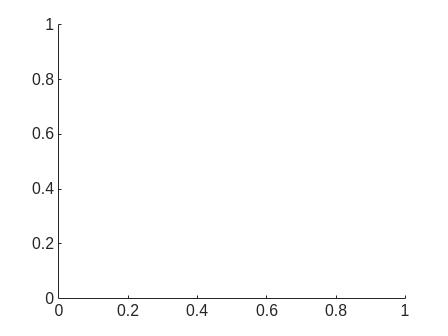

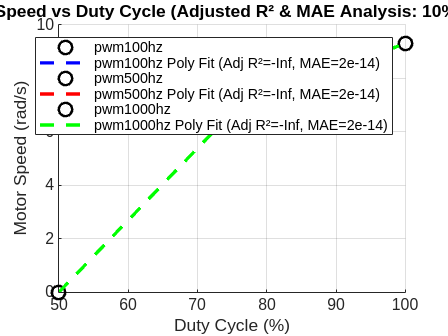

signals = {'Chirp', 'Chirp2', 'Chirp3','Chirp4', 'Chirp5', 'Chirp6', 'Step', 'Step2', 'Step3', 'Step4', 'Step5', 'Step6', 'Ramp', 'Ramp2', 'Ramp3', ...
            'Ramp4', 'Ramp5', 'Ramp6','sin', 'sin2', 'sin3','sin4', 'sin5', 'sin6', 'Stair', 'Stair2', 'Stair3', 'Stair4', 'Stair5', 'Stair6'};
estimated_params_SSE = zeros(length(signals), 4);
estimated_params_Abs = zeros(length(signals), 4);
estimated_params_RMSE = zeros(length(signals), 4);
estimated_params_NMSE = zeros(length(signals), 4);

% Loop over all signals
for i = 1:length(signals)
    signal_name = signals{i};

    % Load input voltage (V) and measured speed (omega)
    V = eval(['V_input_', signal_name]);

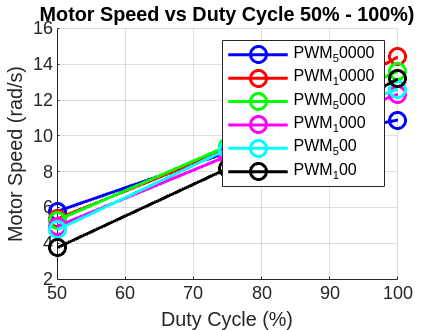

    velocity = eval(['velocity_input_', signal_name]);
    t = eval(['Time_input_', signal_name]);


    t = t(:); 
    V = V(:);
    omega = velocity(:);

    if i <= 6
        % V = V(:) / 12;
       disp("signals{i}")
       disp(signals{i})
       V = V(:) * 12;


    end


    estimated_params_SSE(i, :) = fmincon(@(p) cost_function_SSE(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                                         params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_Abs(i, :) = fmincon(@(p) cost_function_absolute(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                                         params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_RMSE(i, :) = fmincon(@(p) cost_function_rmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                                         params_init, [], [], [], [], lb, ub, [], options);
    estimated_params_NMSE(i, :) = fmincon(@(p) cost_function_nmse(p, Rm_fixed, Lm_fixed, t, V, omega), ...
                                         params_init, [], [], [], [], lb, ub, [], options);

    Ke_SSE  = estimated_params_SSE(i, 1);
    Jm_SSE  = estimated_params_SSE(i, 2);
    Bm_SSE  = estimated_params_SSE(i, 3);
    eta_SSE = estimated_params_SSE(i, 4);
    Km_SSE  = Ke_SSE * max(eta_SSE, 1e-6);
    
    Ke_abs  = estimated_params_Abs(i, 1);
    Jm_abs  = estimated_params_Abs(i, 2);
    Bm_abs  = estimated_params_Abs(i, 3);
    eta_abs = estimated_params_Abs(i, 4);
    Km_abs  = Ke_abs * max(eta_abs, 1e-6);
    
    Ke_rmse  = estimated_params_RMSE(i, 1);
    Jm_rmse  = estimated_params_RMSE(i, 2);
    Bm_rmse  = estimated_params_RMSE(i, 3);
    eta_rmse = estimated_params_RMSE(i, 4);
    Km_rmse  = Ke_rmse * max(eta_rmse, 1e-6);
    
    Ke_nmse  = estimated_params_NMSE(i, 1);
    Jm_nmse  = estimated_params_NMSE(i, 2);
    Bm_nmse  = estimated_params_NMSE(i, 3);
    eta_nmse = estimated_params_NMSE(i, 4);
    Km_nmse  = Ke_nmse * max(eta_nmse, 1e-6);

    %% Display Results for the current signal
    fprintf('Estimated Parameters (SSE) for %s:\n', signal_name);
    fprintf('Ke = %.20f, Km = %.20f, Jm = %.20f, Bm = %.20f, Efficiency = %.20f%%\n\n', ...
        Ke_SSE, Km_SSE, Jm_SSE, Bm_SSE, eta_SSE * 100);
    
    fprintf('Estimated Parameters (Absolute Error) for %s:\n', signal_name);
    fprintf('Ke = %.20f, Km = %.20f, Jm = %.20f, Bm = %.20f, Efficiency = %.20f%%\n\n', ...
        Ke_abs, Km_abs, Jm_abs, Bm_abs, eta_abs * 100);
    
    fprintf('Estimated Parameters (RMSE) for %s:\n', signal_name);
    fprintf('Ke = %.20f, Km = %.20f, Jm = %.10f, Bm = %.10f, Efficiency = %.20f%%\n\n', ...
        Ke_rmse, Km_rmse, Jm_rmse, Bm_rmse, eta_rmse * 100);
    
    fprintf('Estimated Parameters (NMSE) for %s:\n', signal_name);
    fprintf('Ke = %.20f, Km = %.20f, Jm = %.20f, Bm = %.20f, Efficiency = %.20f%%\n\n', ...
        Ke_nmse, Km_nmse, Jm_nmse, Bm_nmse, eta_nmse * 100);

    % Simulate motor speed using the estimated parameters
    omega_sim = motor_model(estimated_params_Abs(i, :), Rm_fixed, Lm_fixed, t, V);
    
    % Plot the results for this signal
    figure(1); clf;
    plot(t, omega, 'b', 'LineWidth', 1.5); 
    hold on;
    plot(t, omega_sim, 'r--', 'LineWidth', 1.5);
    xlabel('Time (s)');
    ylabel('Motor Speed (rad/s)');
    legend('Measured', 'Estimated');
    set(gca, 'Color', [0 0 0]); % Set axis background to black
    title(['Motor Parameter Estimation - ', signal_name]);
    grid on;

    % Save the plot for this signal
    saveas(gcf, ['motor_estimation_', signal_name, '.png']);
end

% Create a table with all the estimated parameters for each signal
resultsTable = array2table([estimated_params_SSE, estimated_params_Abs, estimated_params_RMSE, estimated_params_NMSE], ...
                           'VariableNames', {'Ke_SSE', 'Jm_SSE', 'Bm_SSE', 'Eff_SSE', ...
                                             'Ke_Abs', 'Jm_Abs', 'Bm_Abs', 'Eff_Abs', ...
                                             'Ke_RMSE', 'Jm_RMSE', 'Bm_RMSE', 'Eff_RMSE', ...
                                             'Ke_NMSE', 'Jm_NMSE', 'Bm_NMSE', 'Eff_NMSE'}, ...
                           'RowNames', signals);  % Row names are the signal names

% Display the results table
disp(resultsTable);

mean_value_ten = cell(1, 10);


for i = 1:10
    sum = 0;  
    count = 0;
    
    disp(i);

    for j = 1:1000
        if data{i}{14}.Values.Data(j) >= 0
            sum = sum + data{i}{14}.Values.Data(j);  
            count = count + 1;  
        end
    end

    if count >= 0
        mean_value = sum / count;  
    else
        mean_value = NaN; 
    end

    mean_value_ten{i} = mean_value;

    fprintf('Mean of data for index %d: %.4f\n', i, mean_value);
end



t = {10, 20, 30, 40, 50, 60, 70, 80, 90,100};  
t_numeric = zeros(1, length(t));
for i = 1:length(t)
    if ischar(t{i}) || isstring(t{i})
        t_numeric(i) = str2double(t{i}); 
    else
        t_numeric(i) = t{i};  
    end
end

figure();
plot(t_numeric, cell2mat(mean_value_ten), 'b', 'LineWidth', 1.5);
hold on;
xlabel('Duty Circle');
ylabel('Motor Speed (rad/s)');
grid on;



writetable(resultsTable,'resultsTable_estimate_table.csv');

% Time_input_Chirp   = double(Chirp{1}{1}.Values.Time);
% Time_input_Chirp2  = double(Chirp{2}{1}.Values.Time);
% Time_input_Chirp3  = double(Chirp{3}{1}.Values.Time);
% Time_input_Step    = double(Step{1}{6}.Values.Time);
% Time_input_Step2   = double(Step{2}{6}.Values.Time);
% Time_input_Step3   = double(Step{3}{6}.Values.Time);
% Time_input_Ramp    = double(Ramp{1}{3}.Values.Time);
% Time_input_Ramp2   = double(Ramp{2}{3}.Values.Time);
% Time_input_Ramp3   = double(Ramp{3}{3}.Values.Time);
% Time_input_sin     = double(SineWave{1}{3}.Values.Time);
% Time_input_sin2    = double(SineWave{2}{3}.Values.Time);
% Time_input_sin3    = double(SineWave{3}{3}.Values.Time);
% Time_input_Stair   = double(Stair{1}{5}.Values.Time);
% Time_input_Stair2  = double(Stair{2}{5}.Values.Time);
% Time_input_Stair3  = double(Stair{3}{5}.Values.Time);

% Input voltage signals (from your Simulink or CSV file)
% V_input_Chirp   = double(Chirp{1}{1}.Values.Data);
% V_input_Chirp2  = double(Chirp{2}{1}.Values.Data);
% V_input_Chirp3  = double(Chirp{3}{1}.Values.Data);
% V_input_Step    = double(Step{1}{6}.Values.Data);
% V_input_Step2   = double(Step{2}{6}.Values.Data);
% V_input_Step3   = double(Step{3}{6}.Values.Data);
% V_input_Ramp    = double(Ramp{1}{3}.Values.Data);
% V_input_Ramp2   = double(Ramp{2}{3}.Values.Data);
% V_input_Ramp3   = double(Ramp{3}{3}.Values.Data);
% V_input_sin     = double(SineWave{1}{3}.Values.Data);
% V_input_sin2    = double(SineWave{2}{3}.Values.Data);
% V_input_sin3    = double(SineWave{3}{3}.Values.Data);
% V_input_Stair   = double(Stair{1}{5}.Values.Data);
% V_input_Stair2  = double(Stair{2}{5}.Values.Data);
% V_input_Stair3  = double(Stair{3}{5}.Values.Data);